% MANUALLY LOAD .mat FILES One Mouse @ a time

% CALC'S FOR LATER
RoundXpts = round(abs(ypts)); %switch x & y
RoundYpts = round(abs(xpts));


clear PTSdfof % pulling fluoresence data from just teh points picked in threshPassAnalysis script
for i = 1:length(xpts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end
display('size of PTSdfof is: ')
size(PTSdfof)


% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
uniqueContrasts = unique(con); % for looping over contrast values later


% DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); % save in new vector that is a list 
% of trial conditions ordered by trial

uniqueDurations = unique(dur); % for looping later


% common figure calc's

reigons = {'V1','LM','RL','PM','control'};
cons4Legend = {'0','0.03','0.063','0.125','0.25','0.5','1'};
durs4Legend = {'16','33','66','133','266'};


% GROUP ANALYSES


% MEAN CRF OVER SESSIONS/MICE
% CRF w/ PEAK (MEAN @ LATENCY) --> determined by looking at latency.. just taking mean at these frames, not using max function
% CRF over frames 14-16

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;

subplotNum = 1;
r = 1;

clear sess1_AllPtsContMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof

figure 
suptitle('Contrast Response Functions for Each Point')
clear i 
for i = 1:length(xpts)
    
    clear sq5FramesOverTrialsPTSdfof
    clear meanOverFramesSq5FramesOverTrialsPTSdfof
    clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contStdErr
    
    for c = 1:length(uniqueContrasts)
        
        clear cthTrials
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c);  
        
        % CRF POINTS for each contrast, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthTrials));
        
        % take the mean over frames
        %returns 1 x 76 (trials)
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th CRF value for this point
        % creates 1 x 7 (contrasts)
        contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
%         stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
%         contStdErr(1,c) = stdErr;
        
    end 
    % UNCOMMENT THE RIGHT ONE
    
    % these should each return a 5x7, one for each CRF for each point/subplot
    
    % clear sess1_allPtCRF
    % sess1_allPtCRF(i,:) = contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
    
    % clear sess2_allPtCRF
    % sess2_allPtCRF(i,:) = contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;

end


    % now let's concatenate the two sessions
    % each session is 2 dimensions - 5 rows (points) x 7 columns(CRF values)
    % let's make the 3rd dimension be 'sessions'
    clear allSessAllPts
    allSessAllPts = cat(3,sess1_allPtCRF,sess2_allPtCRF);
        

% We want to find CRF for each Point, and for each session.
% then we want to average the CRF's at one point from each session together

figure % one subplot for each point. one CRF averaged across 2 sessions for each mouse
suptitle('Mean CRF per visual area for 1 mouse Over 2 Sessions')

clear r 
r = 1;

clear subplotNum
subplotNum = 1;

clear CRFithPtSess1
clear transSqCRFpt1Sess1 

clear CRFithPtSess2
clear transSqCRFithPtSess2

clear twoSessCRFithPt
clear transSqTwoSessCRFithPt

clear meanTwoSessCRFithPt
clear stdErr

clear i
for i = 1:length(xpts)
        
    % allSessAllPts is points (5) x contrasts (7) x sessions (2)
    % we are selecting a 1 x 7 x 1... might need squeeze & transpose...
    % trying to get 1x7 CRF at ith point, session 1
    CRFithPtSess1 = allSessAllPts(i,:,1)    ; 
    transSqCRFpt1Sess1 = squeeze(CRFithPtSess1)';
    
    CRFithPtSess2 = allSessAllPts(i,:,2)   ;  
    transSqCRFithPtSess2 = squeeze(CRFithPtSess2)';
    
    % concatenate them so i can take stdErr
    % should give me 2 x 7
    twoSessCRFithPt = cat(3,transSqCRFpt1Sess1,transSqCRFithPtSess2);
    transSqTwoSessCRFithPt = squeeze(twoSessCRFithPt)';
    % take mean across sessions
    % should give me 1x7
    meanTwoSessCRFithPt = mean(transSqTwoSessCRFithPt,1);
    
    % take stdErr across sessions
    stdErr = std(transSqTwoSessCRFithPt,1)/sqrt(size(transSqTwoSessCRFithPt,1)); % size sessions is the 1st dimension at this point 
    
    clear x_axis
    x_axis = [1 2 3 4 5 6 7] ;
    subplot(2,3,i)
    clear myplot
    myplot = errorbar(x_axis,meanTwoSessCRFithPt,stdErr);
    
    clear st
    st = title(sprintf('%s', reigons{r}));
    ylim([-0.02 0.09]) 
    xlim([0, 8])
        
    ax=myplot.Parent;
    ax.XMinorTick = 'on'; % more tick marks
    set(ax, 'XTick', 0:1:8);
    
     if subplotNum == 1
     xlabel('contrasts plotted as log linear')
     ylabel('df/f')
        
    end 

    r = r+1
 subplotNum = subplotNum+1
 
end 

r =      2


subplotNum =      2


r =      3


subplotNum =      3


r =      4


subplotNum =      4


r =      5


subplotNum =      5


r =      6


subplotNum =      6


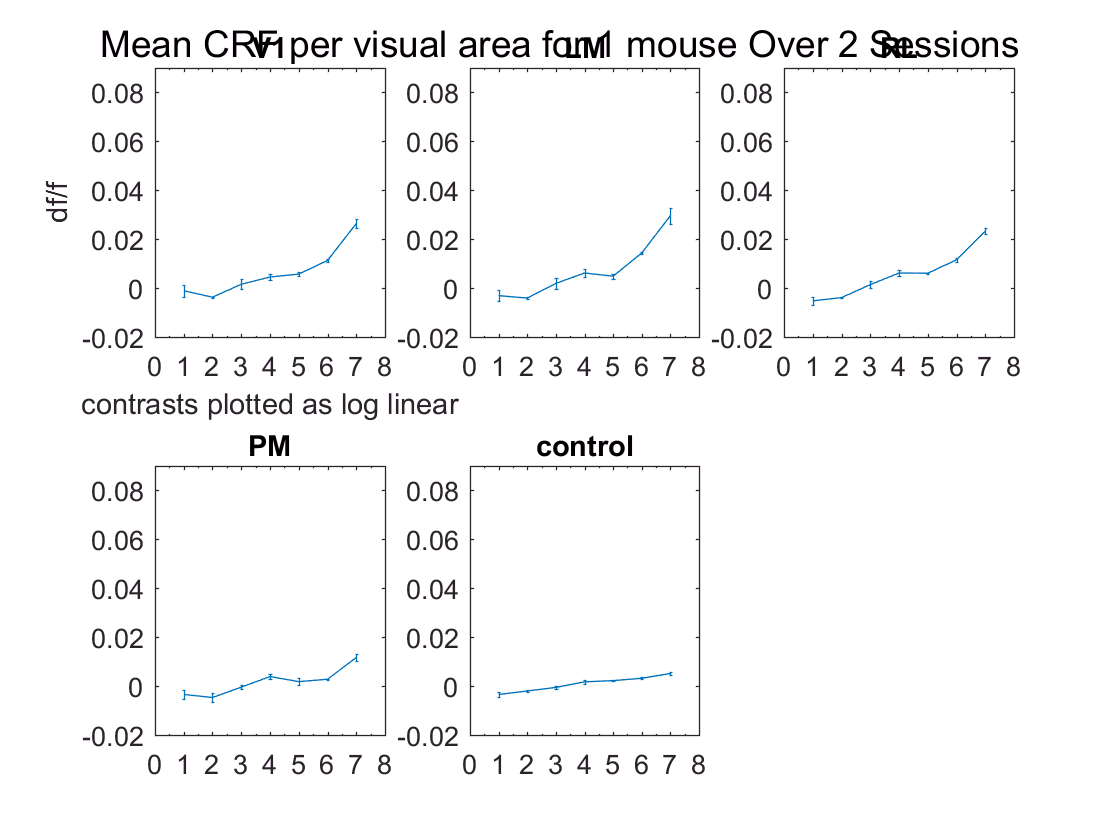


hold on

    
    % I'm going to try this the stupid way first
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5 6 7];
    crfChart = errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    st = title(sprintf('%s', reigons{r}));
    ylim([-0.02 0.05]) 
    xlim([0, 8])
    ylabel('df/f')
    xlabel('contrasts plotted as log linear')
    
    ax=crfChart.Parent;
    ax.XMinorTick = 'on'; %more tick marks
    set(ax, 'XTick', 0:1:8);
%     clear xt
%     xt={'0' ; '0.03' ; '0.0625' ; '0.125' ; '0.25'; '0.5'; '1';} ; 
%     set(gca,'xtick',1:7);
%     set(gca,'xticklabel',xt);
    
subplotNum = subplotNum+1;
r = r+1;
    
end 